# Lab 3 - Asking a statistical question

Thomas Conaway

Lab Partners: Jeff, Avis

Time: 7 hours (including lab time)

## Problem 1

When collecting data points it is possible for "bad data" to be introduced whenever glitches or other errors occur. We would like to be able to identify and throw away points which are obviously anomalous. On a probability distribution, the highly improbable values which lie far out on the tails are then likely candidates for removal, as it is unlikely for our chosen distribution model to produce them randomly.

For an experiment which requires a consistent 12 K temperature to perform reliably, we can examine the temperature meta-data to look for instances where the temperature varied significantly and throw out this data. It is possible that good data may be lost, such as if the measure of temperature was wrong but he true temperature remained consistent, but without any way of knowing this we just have to accept this as a cost of removing the truly bad data.

To explore the consequences of this further, I will assess the 12 K temperature scenario above using some randomly generated data. I will generate 100,000 random "good" data points that will be Gaussian distributed around a mean of 12 K with a standard deviation 0.4 K (the precision of the thermometry and the thermal control system). I will then toss in some bad data, and will attempt to identify it within the distribution and throw it out.

A) Generating data and plotting it in histograms:

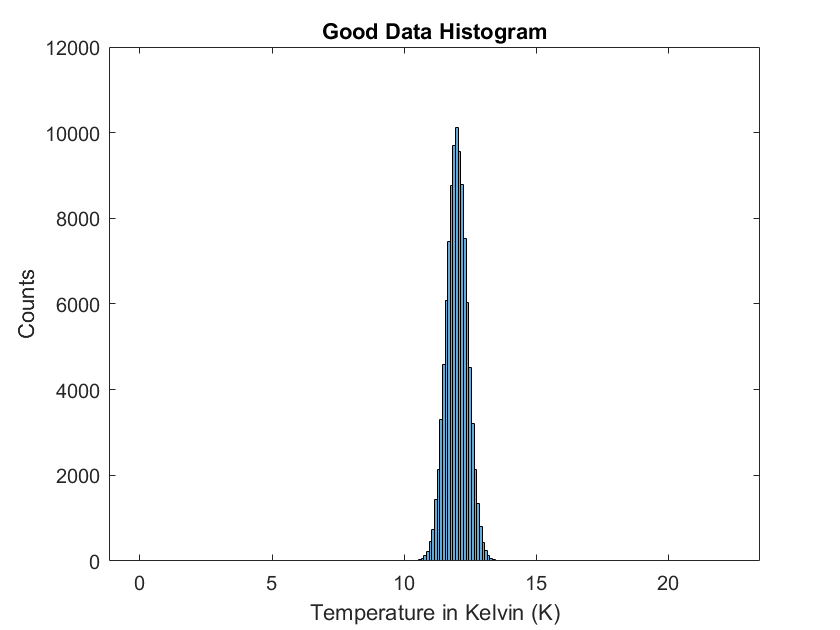

clc; clear; close all;
gooddist = random("Normal",12,0.4,[1,100000]);
% testdist = round(gooddist,1)
badpoints = [10.,10.3,2.1,0.,0.,15.6,22.3,12.7]; % 8 total
baddist = [gooddist,badpoints];
bins = 0:0.1:22.4;
bins = bins - 0.05;
histogram(gooddist,bins);
% xlim([10,14]);
title("Good Data Histogram");
xlabel("Temperature in Kelvin (K)");
ylabel("Counts");

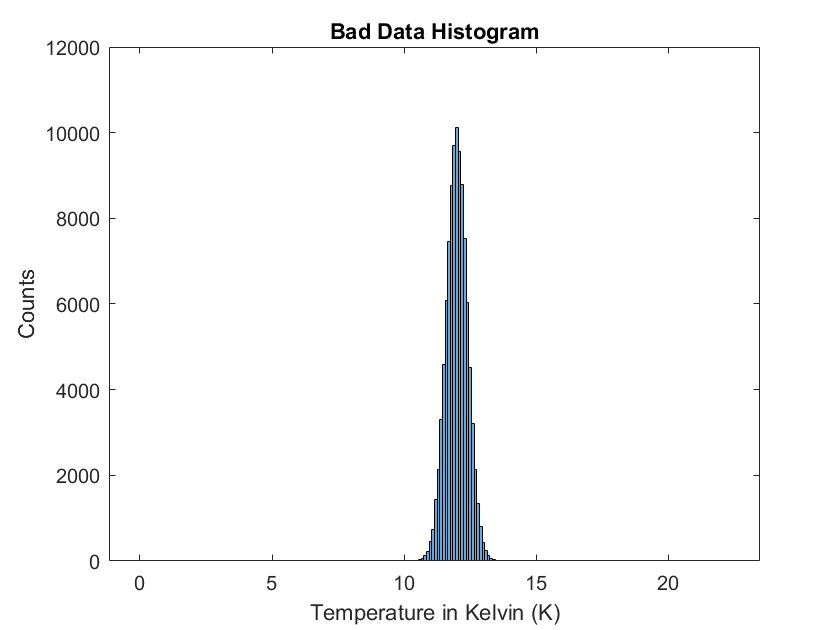

histogram(baddist,bins);
title("Good and Bad Data Histogram");
xlabel("Temperature in Kelvin (K)");
ylabel("Counts");

% xlim([10,14]);

The histograms are visually indistinguishable from eachother; eight bad points did not result in a significant change to the histogram.

Most of the bad data points are far enough from the mean that truncating the ends of the distribution would eliminate them at the cost of very few good data points, but if I truncate too close to the mean then a significant portion of good data will be lost. What are the tradeoffs when discarding data points beyond a chosen threshold? This question is important to ask because its answer will help us decide if removing bad data in this manner to improve the quality of the set is a worthwhile endeavor.

I will choose a threshold value that will serve as the distance from the histogram's mean, in both directions, for the location of the cut, which will divide the histogram bins into two categories: cut and kept. I will then count the number of good and bad data points within each category, keeping tally in a truth table.

threshold = 1.7;

goodvalues = histcounts(gooddist,bins);
goodtails = [goodvalues(1:(12-threshold)*10),goodvalues((12+threshold)*10:length(goodvalues))];
goodcut = sum(goodtails); %
goodmid = [goodvalues((12-threshold)*10+1:(12+threshold)*10-1)];
goodkept = sum(goodmid); %

badvalues = histcounts(baddist,bins);
badtails = [badvalues(1:(12-threshold)*10),badvalues((12+threshold)*10:length(badvalues))];
badmid = [badvalues((12-threshold)*10+1:(12+threshold)*10-1)];
badkept = sum(badmid)-sum(goodmid); %
badsum = sum(badtails);
badcut = badsum - goodcut; %

Threshold = {'Kept';'Cut'};
Good = [goodkept;goodcut];
Bad = [badkept;badcut];

% to self: look up PCA

T = table(Good,Bad,'RowNames',Threshold)

T = 2×2 table
            Good     Bad
            _____    ___

    Kept    99991     2 
    Cut         9     6 


B) By adjusting the threshold we can see that choosing small (under 1.7) values will result in more good data being thrown out than bad. A threshold higher than 2.0 results in almost no good data being lost but only removes only the most distal of the bad data. The number of omissions of good data is predictable in that it relates to the proportion of area under the Gaussian curve formed by the histogram, where thresholds that fall within the central bulk cause a significant number data points to be lost when truncating.

C) Some bad data will be kept for all but the most minute of thresholds we choose. Bad data that is closer to the center of our histogram cannot be removed using this method without losing a significant amount of good data. This is unavoidable, but if we suspect that most of our bad data lies far from the center then lowering the threshold will not result in many commissions (bad data getting in) while very high thresholds are required to make a significant number of mistakes.

## Problem 2

For stationary stars in the sky, repeated measurements of their position results in small displacements owing to the atmospheric effects and imprecisions in our instruments. The probability distribution of these displacements follows a 2d bivariate normal distribution centered at 0 with a RMS value of 1 arcsecond (the double integral over all 2d space is also 1, just like the 1d Gaussian case). This will give the probability that a stationary object will be measured to have a certain displacement (in x and y) about its fixed location.

For a moving object in the sky (such as an asteroid) a significant displacement is expected to be measured. However, there is still a small chance for the stationary background (the random fluctuations in measured displacements) to produce such a large displacement when imaging a stationary object. We'd still like to be fairly certain that what we detect is, in fact, an asteroid, and not some anomaly that occurred when looking at a stationary star.

- So we ask: what radial distance (in arcseconds) gives us a 'five sigma' (1 in 3.5 million) probability threshold for the stationary star background to produce a displacement signal as (or more) asteroid-like than the real thing?

- In mathematical terms: what is the "z-value" radius for the 2d Gaussian that will produce a 1 in 3.5 million probability when integrating (double integral) the 2d bivariate normal distribution starting from the boundary circle (radius = z-value, centered on the origin) all the way out to infinity in the xy-plane.

% The amplitude of 2d gaussian may be given by another distribution. We can use the blue book (map diagram?) to find
% it. The book was not particularly illuminating so I am using the generalized description of the Gaussian
% distribution following the same method we used in the 1d case.

## Problem 3

Cosmic rays are charged particles that spiral through the magnetic fields of galaxies over great distances. Here on earth they fly in from all directions on strange paths, but the high-energy ones that reach earth will, for significant speeds, be percieved as travelling nearly in a straight line. When these are blocked by the sun and the moon they will form "holes" in the cosmic ray sky.

In a region of sky the size of a moon, we find that the rate of cosmic rays we measure is 1 per minute (random in time). We then observe the moon itself over a period of time (8 hours a day for 15 days, when not near the horizon) and we see a total 6800 cosmic rays. We would like to find the significance of our observation.

- We ask: what is the probability of a moon sized patch of sky, over a period of time, producing a total cosmic ray count that looks as (or more) like what we measure (and expect to measure) when looking at the moon?

- The background probability distribution function describes an average rate for random events, which is precisely what a Poisson distribution models. Ours has a mean rate of 1 cosmic ray per minute for the moon-sized patch of unobstructed sky. We can then integrate (sum) this distribution over the length of time given (8 hours a day for 15 days) to get the probability distribution for the sum of the background to test against the measured value of 6800 cosmic rays when looking at the moon. When summing Poisson distributions, the resulting distribution's mean is the sum of the means of the distributions summed, so we can quickly calculate that the summed background has a mean rate of 1*60*8*15=7200 cosmic rays over this long interval of time and can produce the sum distribution directly with this. We expect the moon to block most cosmic rays, so "more signal-like" will be more towards 0 cosmic rays detected. We integrate from 0 to 6800 on the sum background probability distribution to get a probability for producing "signal-like" values in this region, and then we convert it into a sigma value by means of finding a z-value for that probability on a standard normal distribution.

clc; clear; close all;

sig = 1.0133e-06

sumpoisson = makedist("Poisson","lambda",7200);

ans = 4.7507

sig = cdf(sumpoisson,6800)
abs(norminv(sig))

        3. We find that our moon shadow detection has a significance just under 5 sigma.